syms m1 m2 k1 k2 b1 b2 v1 v2 x1 x2 wt wtp u
vp=(1/m1)*(u-k1*(x1-x2)-b1*(v1-v2))

$$vp = -\frac{b_{1}\,\left(v_{1}-v_{2}\right)-u+k_{1}\,\left(x_{1}-x_{2}\right)}{m_{1}}$$

x1p=v1

$$x1p = v_{1}$$

v2p=(1/m2)*(k1*(x1-x2)+b1*(v1-v2)-u-k2*(x2-wt)-b2*(v2-wtp))

$$v2p = \frac{b_{1}\,\left(v_{1}-v_{2}\right)-u-b_{2}\,\left(v_{2}-\mathrm{wtp}\right)+k_{2}\,\left(\mathrm{wt}-x_{2}\right)+k_{1}\,\left(x_{1}-x_{2}\right)}{m_{2}}$$

x2p=v2

$$x2p = v_{2}$$


xe=[v1,x1,v2,x2]

$$xe = \left(\begin{array}{cccc} v_{1} & x_{1} & v_{2} & x_{2} \end{array}\right)$$

y=x1

$$y = x_{1}$$

A=jacobian([vp,x1p,v2p,x2p],xe)

$$A = \left(\begin{array}{cccc} -\frac{b_{1}}{m_{1}} & -\frac{k_{1}}{m_{1}} & \frac{b_{1}}{m_{1}} & \frac{k_{1}}{m_{1}}\\ 1 & 0 & 0 & 0\\ \frac{b_{1}}{m_{2}} & \frac{k_{1}}{m_{2}} & -\frac{b_{1}+b_{2}}{m_{2}} & -\frac{k_{1}+k_{2}}{m_{2}}\\ 0 & 0 & 1 & 0 \end{array}\right)$$

B=jacobian([vp,x1p,v2p,x2p],u)

$$B = \left(\begin{array}{c} \frac{1}{m_{1}}\\ 0\\ -\frac{1}{m_{2}}\\ 0 \end{array}\right)$$

C=jacobian(y,xe)

$$C = \left(\begin{array}{cccc} 0 & 1 & 0 & 0 \end{array}\right)$$

D=jacobian(y,u)

$$D = 0$$

E=jacobian([vp,x1p,v2p,x2p],wt)

$$E = \left(\begin{array}{c} 0\\ 0\\ \frac{k_{2}}{m_{2}}\\ 0 \end{array}\right)$$

F=jacobian([vp,x1p,v2p,x2p],wtp)

$$F = \left(\begin{array}{c} 0\\ 0\\ \frac{b_{2}}{m_{2}}\\ 0 \end{array}\right)$$


m1=2500

m1 = 2500

m2=320

m2 = 320

k1=80

k1 = 80

k2=500

k2 = 500

b1=350

b1 = 350

b2=15020

b2 = 15020


A=double(eval(A))

A =    -0.1400   -0.0320    0.1400    0.0320
    1.0000         0         0         0
    1.0938    0.2500  -48.0313   -1.8125
         0         0    1.0000         0


B=double(eval(B))

B =     0.0004
         0
   -0.0031
         0


C=double(eval(C))

C =      0     1     0     0


D=double(eval(D))

D = 0

E=double(eval(E))

E =          0
         0
    1.5625
         0


F=double(eval(F))

F =          0
         0
   46.9375
         0



[num,den]=ss2tf(A,B,C,D)

num =          0         0    0.0004    0.0188    0.0006


den =     1.0000   48.1712    8.4157    1.7207    0.0500


ft=tf(num,den)


ft =
 
       0.0004 s^2 + 0.01877 s + 0.000625
  --------------------------------------------
  s^4 + 48.17 s^3 + 8.416 s^2 + 1.721 s + 0.05
 
Continuous-time transfer function.



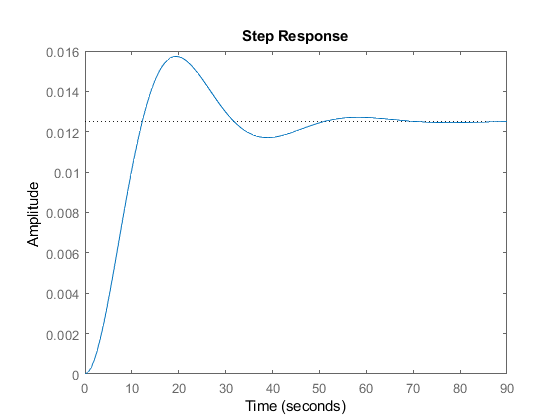

step(ft)

[mag,phase,wout] = bode(ft);
n=1;
while true
    if 20*log10(mag(:,:,n))>20*log10(mag(:,:,1))-3%
        n=n+1;
    else
        break
    end
end
wc=wout(n,1)

wc = 0.2537

wMuestr=wc/20

wMuestr = 0.0127

ftDisc=c2d(ft,wMuestr,'tustin')


ftDisc =
 
  1.599e-08 z^4 + 7.336e-09 z^3 - 2.463e-08 z^2 - 7.33e-09 z + 8.653e-09
  ----------------------------------------------------------------------
              z^4 - 3.531 z^3 + 4.594 z^2 - 2.595 z + 0.5321
 
Sample time: 0.012683 seconds
Discrete-time transfer function.



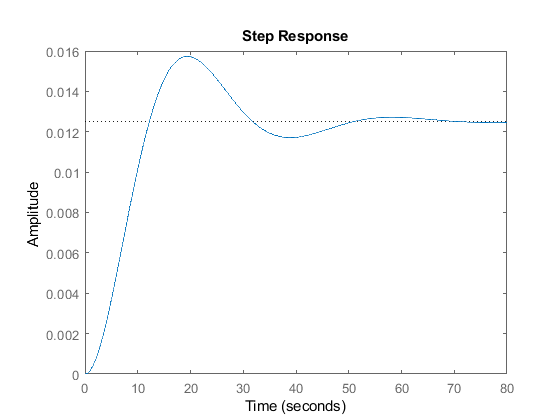

step(ftDisc)